## Optimize IPTG concentration for FA2 strain

modelName = 'FA234';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Manual Switch3",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','0') % FA2 model

p = sdo.getParameterFromModel(modelName,'IPTG');

p.Value = 100;
p.Minimum = 0;
p.Maximum = 1000;
p.Scale = 1000;
p.Free = 1;

options = sdo.OptimizeOptions;
options.Method = 'fmincon';

Exp = sdo.Experiment(modelName);
Exp = setEstimatedValues(Exp,p);

FFASignal = Simulink.SimulationData.Signal;
FFASignal.Name = 'Fatty acid';
FFASignal.BlockPath = modelName + "/GainFA";
FFASignal.PortType = 'outport';
FFASignal.PortIndex = 1;
FFASignal.Values = timeseries((1:25)',(1:25)'); % What does this mean?

Exp.OutputData = FFASignal; % add the signal object to the experiment

Simulator = createSimulator(Exp);
estFcn = @(p) optInputObjective(p,Simulator,Exp);

val = optInputObjective(p,Simulator,Exp);
val.F

ans = -1.4494

tic
[optInput,optInputInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 15-Nov-2023 22:31:44

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      3     -1.44936            0
    1      7     -1.61762            0         0.07         2.08
    2     16     -1.61768            0      0.00131         1.46
    3     17     -1.61768            0     5.73e-05         1.46
局所的最小値の可能性があります。制約が満たされました。

現在のステップ サイズがステップ サイズの許容誤差値未満で、
制約が制約の許容誤差値の範囲内で満たされているため、
fmincon は停止しました。
 
optInput =
 
       Name: 'IPTG'
      Value: 31.3121
    Minimum: 0
    Maximum: 1000
       Free: 1
      Scale: 1000
       Info: [1×1 struct]

 
1x1 param.Continuous
 
lists of methods, superclasses
 


optInputInfo = フィールドをもつ struct :
               F: -1.6177
       Gradients: [1×1 struct]
        exitflag: 2
      iterations: 3
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 16.646559 秒です。


maxFFA_FA2 = -optInputInfo.SolverOutput.fval;

save('optInput_FA2','optInput')
sdo.setValueInModel(modelName,optInput);

## Plot the convex curve

setPointValues = logspace(0,3,100); % 1-1000 uM IPTG
spv_length = length(setPointValues);
for i = 1:1:spv_length
    in(i) = Simulink.SimulationInput(modelName);
    in(i) = in(i).setBlockParameter(modelName + "/To optimize input",...
        'Value',num2str(setPointValues(i)));
end

out_FA2 = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[15-Nov-2023 22:33:16] シミュレーションの実行中...
[15-Nov-2023 22:33:18] シミュレーション実行 1/100 が完了
[15-Nov-2023 22:33:20] シミュレーション実行 2/100 が完了
[15-Nov-2023 22:33:21] シミュレーション実行 3/100 が完了
[15-Nov-2023 22:33:22] シミュレーション実行 4/100 が完了
[15-Nov-2023 22:33:23] シミュレーション実行 5/100 が完了
[15-Nov-2023 22:33:24] シミュレーション実行 6/100 が完了
[15-Nov-2023 22:33:25] シミュレーション実行 7/100 が完了
[15-Nov-2023 22:33:26] シミュレーション実行 8/100 が完了
[15-Nov-2023 22:33:27] シミュレーション実行 9/100 が完了
[15-Nov-2023 22:33:28] シミュレーション実行 10/100 が完了
[15-Nov-2023 22:33:29] シミュレーション実行 11/100 が完了
[15-Nov-2023 22:33:30] シミュレーション実行 12/100 が完了
[15-Nov-2023 22:33:31] シミュレーション実行 13/100 が完了
[15-Nov-2023 22:33:32] シミュレーション実行 14/100 が完了
[15-Nov-2023 22:33:33] シミュレーション実行 15/100 が完了
[15-Nov-2023 22:33:34] シミュレーション実行 16/100 が完了
[15-Nov-2023 22:33:35] シミュレーション実行 17/100 が完了
[15-Nov-2023 22:33:36] シミュレーション実行 18/100 が完了
[15-Nov-2023 22:33:37] シミュレーション実行 19/100 が完了
[15-Nov-2023 22:33:38] シミュレーション実行 20/100 が完了
[15-Nov-2023 22:33:39] シミュレーション実行 21/100 が完了
[15-Nov-2023 22:33:40] シミ

out_FA2 = 1x100 Simulink.SimulationOutput 配列



FFA_end_FA2 = zeros(spv_length,2);
FFA_end_FA2(:,1) = setPointValues;
for i = 1:1:spv_length
    FFA_end_FA2(i,2) = out_FA2(i).logsout{1}.Values.Data(end);
end

FFAData = zeros(6,2);
FFAData(:,1) = [0 10 40 100 400 1000]';
load("FA2Data.mat")
for expIdx = 1:6
    FFAData(expIdx,2) = FA2Data(8,expIdx + 1,2);
end

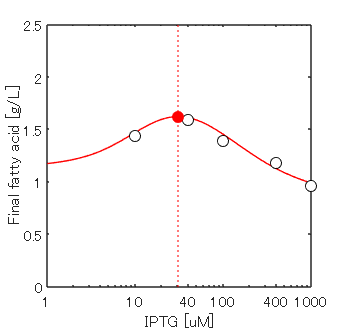

figure('Position', [120 120 250 240]);
plot(FFA_end_FA2(:,1),FFA_end_FA2(:,2),'r-')
xline(optInput.Value,'r:')
xlim([1 1000])
ylim([0 2.5])
xlabel('IPTG [uM]')
xticks([1 10 40 100 400 1000])
% yticks([0 20 40 60 80])
ylabel('Final fatty acid [g/L]')
hold on
plot(FFAData(:,1),FFAData(:,2),'ko','MarkerFaceColor','w')
plot(optInput.Value,maxFFA_FA2,'ro','MarkerFaceColor','r')
hold off
set(gca,'xscale','log')